# 3-D Left Ventricle/Left Atrium Segmentation Using Deep Learning

## Prepare Data for Training

`Raw_Data` has three subdirectories: `imagesTs`, `LA-labelsTs`, and `LV-labelsTs`. 

Each scan is a 3-D array where the three dimensions correspond to the height, width, and depth of a 3-D image. The data set has 80 volumes with voxel labels. We will split the 80 volumes into three independent sets to use for training, validation, and testing.

### Preprocess Data

To train the 3-D U-Net network more efficiently, preprocess the CT data by using the `preprocessCTDataset` helper function. The helper function performs these operations:

- First only keep the volumes with depth 256 (removed 6 files). Split the remaining 74 training volumes into 51 training, 15 validation, and 8 test sets. (7:2:1)

- Crop the data to a region containing left ventricle & left atrium (only crop in z direction). Cropping reduces the size of data while retaining the most critical part of each CT volume and its corresponding labels.

- Normalize each volume by subtracting the minimum value and dividing by the range (i.e., the difference between the maximum and minimum values) of the cropped region. This converts values to [0 1].

Preprocessing the data can take about 10 minutes to complete. 

sourceDataLoc = "Raw_Data";
preprocessDataLoc = "preprocessedDataset";
preprocessCTDataset(preprocessDataLoc,sourceDataLoc);

### Create Random Patch Extraction Datastore for Training and Validation

To read and manage the 3-D training image data, create an [`imageDatastore`](docid:matlab_ref#butueui-1) object. Specify a custom read function, `matRead`, to read the image data from MAT files. 

volLocTrain = fullfile(preprocessDataLoc,"imagesTr");
voldsTrain = imageDatastore(volLocTrain,FileExtensions=".mat",ReadFcn=@matRead);

To read and manage the labels, create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) object. Specify the same class names as defined for the `classNames` variable. The pixel label ID `1` maps to the `"LA"` class name, the pixel label ID `2` maps to the `"LV"` class name, and the pixel label ID `0` maps to the `"background"` class name.

classNames = ["background", "LA", "LV"];
disp(classNames)

    "background"    "LA"    "LV"



pixelLabelID = [0 1 2]; % background=0, LA=1, LV=2
lblLocTrain = fullfile(preprocessDataLoc,"labelsTr");

pxdsTrain = pixelLabelDatastore(lblLocTrain,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) object that extracts random patches from ground truth images and their corresponding pixel label data. Specify a patch size of 128-by-128-by-128 voxels. Specify the "`PatchesPerImage"` name-value argument to extract 8 randomly positioned patches from each pair of volumes and labels during training. Specify a mini-batch size of 2.

patchSize = [108 108 108];
patchPerImage = 16;
miniBatchSize = 4;
patchdsTrain = randomPatchExtractionDatastore(voldsTrain,pxdsTrain,patchSize, ...
    PatchesPerImage=patchPerImage);
patchdsTrain.MiniBatchSize = miniBatchSize;

Similarly, to manage the validation data set, create `imageDatastore`, `pixeLabelDatastore`, and `randomPatchExtractionDatastore` objects. You can use validation data to evaluate whether the network is continuously learning, underfitting, or overfitting during training.

volLocVal = fullfile(preprocessDataLoc,"imagesVal");
voldsVal = imageDatastore(volLocVal,FileExtensions=".mat", ...
    ReadFcn=@matRead);

lblLocVal = fullfile(preprocessDataLoc,"labelsVal");
pxdsVal = pixelLabelDatastore(lblLocVal,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

patchdsVal = randomPatchExtractionDatastore(voldsVal,pxdsVal,patchSize, ...
    PatchesPerImage=patchPerImage);
patchdsVal.MiniBatchSize = miniBatchSize;

## Read and Display 3-D Pixel Label Data

Read volume and pixel label data. `L` is a categorical matrix, where `L(i,j,k)` is the categorical label assigned to `V(i,j,k)`.

V = read(voldsTrain);
L = read(pxdsTrain);

Display the label categories.

C = categories(L{1})

C = 3×1 cell array
    {'background'}
    {'LA'        }
    {'LV'        }


Visualize the result using the `viewer3d` and `volshow` functions. Display the labels by specifying the `OverlayData` and `OverlayAlpha` name-value arguments.

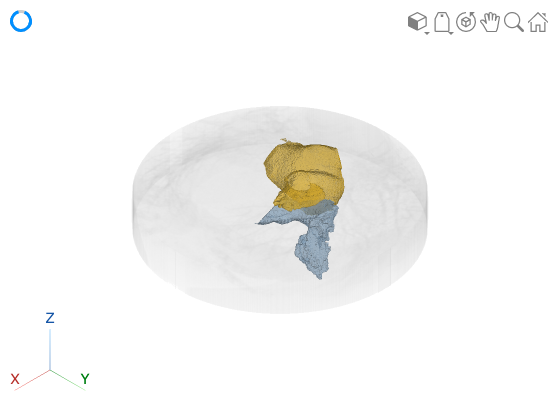

viewer = viewer3d(BackgroundColor="white",BackgroundGradient="off");

h = volshow(V,Parent=viewer, ... 
    RenderingStyle="GradientOpacity", ...
    GradientOpacityValue=0.7, ... 
    Alphamap=linspace(0,0.2,256), ...
    OverlayDisplayRange=[1 3], ...
    OverlayData=L{1}, ...
    OverlayAlpha=0.5);

### Create Animation of Rotating Volume

% Get viewer and figure handles
viewer = h.Parent;
hFig = viewer.Parent;
drawnow

Specify the name of the GIF file in which to save the animation.

filename = "animatedVolume.gif";

Aim the camera at the center of the volume.

sz = size(V);  % Use your volume size
center = sz/2 + 0.5;
viewer.CameraTarget = center;

Specify the number of frames in the animation, then create an array of camera positions in a circle around the center of the volume.

numberOfFrames = 24;
vec = linspace(0, 2*pi, numberOfFrames)';
dist = sqrt(sz(1)^2 + sz(2)^2 + sz(3)^2);
myPosition = center + ([cos(vec) sin(vec) ones(size(vec))]*dist);

At each camera position, update the display and write the frame to the GIF file.

for idx = 1:length(vec)
    % Update the current view
    viewer.CameraPosition = myPosition(idx,:);
    
    % Capture the image using the getframe function
    I = getframe(hFig);
    [indI,cm] = rgb2ind(I.cdata,256);
    
    % Write the frame to the GIF file
    if idx==1
        % Do nothing. The first frame displays only the viewer, not the volume.
    elseif idx == 2
        imwrite(indI,cm,filename,"gif",Loopcount=inf,DelayTime=0)
    else
        imwrite(indI,cm,filename,"gif",WriteMode="append",DelayTime=0)
    end
end

## Define 3-D U-Net Network Architecture

This example uses the 3-D U-Net network [1]. In U-Net, the initial series of convolutional layers are interspersed with max pooling layers, successively decreasing the resolution of the input image. These layers are followed by a series of convolutional layers interspersed with upsampling operators, successively increasing the resolution of the input image. A batch normalization layer is introduced before each ReLU layer. The name U-Net comes from the fact that the network can be drawn with a symmetric shape, like the letter U.

Create a default 3-D U-Net network by using the [`unet3d`](docid:vision_ref#mw_ce5031ae-be49-4e7f-ac3a-b9d5be88fa14) function. Specify two-class segmentation. To avoid border artifacts, also specify valid convolution padding.

numChannels = 1;  % Single channel CT data
inputPatchSize = [patchSize numChannels];
numClasses = 3;
[net,outPatchSize] = unet3d(inputPatchSize, ...
    numClasses,ConvolutionPadding="valid");

Augment the training and validation data by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the `augmentAndCrop3dPatch` helper function. This function is attached to the example as a supporting file. The `augmentAndCrop3dPatch` function performs these operations:

- Randomly rotate and reflect training data to make the training more robust. The function does not rotate or reflect validation data.

- Crop response patches to the output size of the network, 44-by-44-by-44 voxels.

dsTrain = transform(patchdsTrain, ...
    @(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Training"));
dsVal = transform(patchdsVal, ...
    @(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Validation"));

Because the data has already been normalized in the Prepare Data for Training section of this example, data normalization in the [`imageInput3dLayer`](docid:nnet_ref#object_layer.imageinput3dlayer) is unnecessary, so replace the input layer with an input layer that does not have data normalization.

inputLayer = image3dInputLayer(inputPatchSize, ...
    Normalization="none",Name="ImageInputLayer");
net = replaceLayer(net,net.Layers(1).Name,inputLayer);

Alternatively, you can modify the 3-D U-Net network by using the Deep Network Designer app.

% deepNetworkDesigner(net)

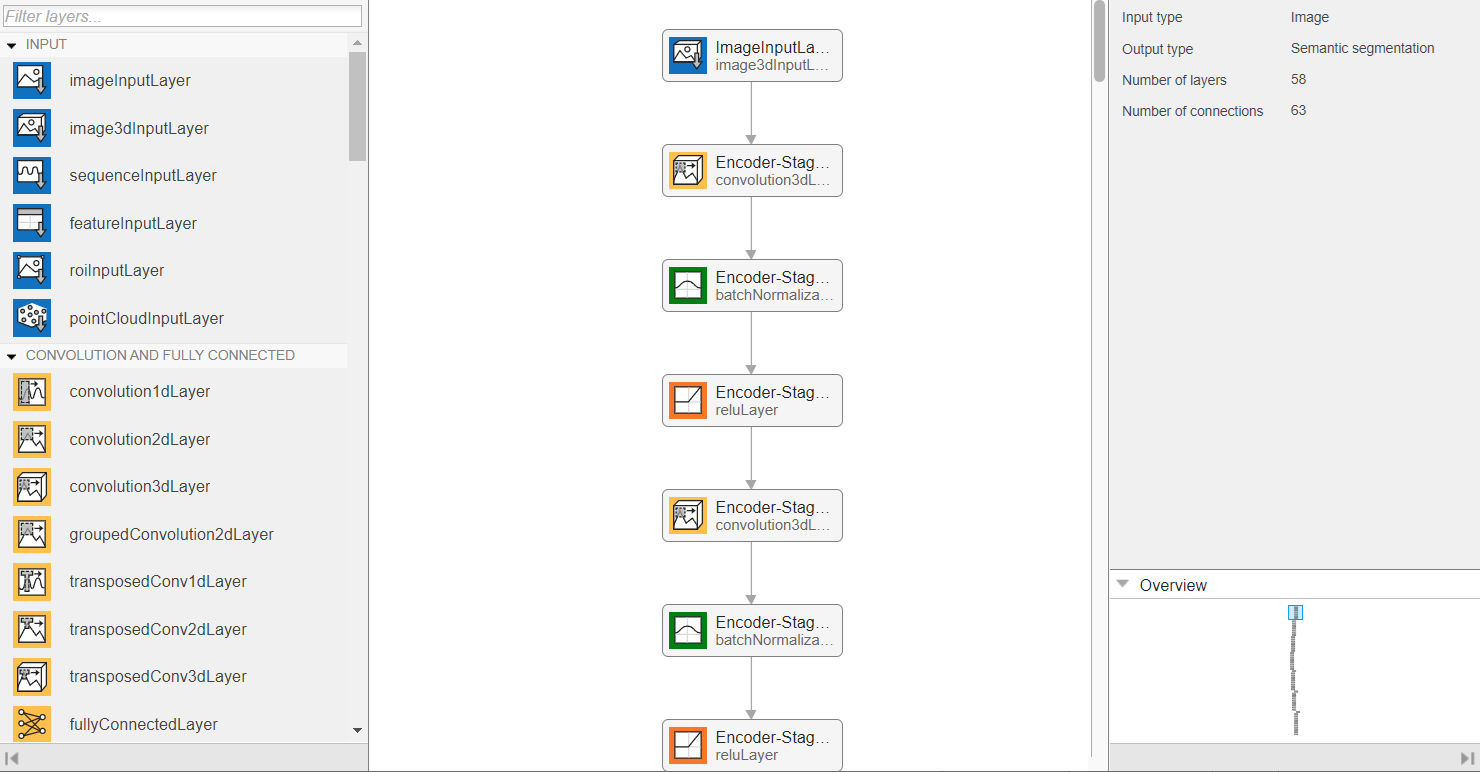


img = batch.inpVol{1};       % The input image patch (for sample 1)

batch = 4×2 table
           inpVol              inpResponse   
    ____________________    _________________

    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}


           inpVol              inpResponse   
    ____________________    _________________

    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}
    {108×108×108 double}    {20×20×20 double}



label = batch.inpResponse{1};

imshow(img(:,:,round(end/2)))

## Train 3-D U-Net

### Specify Training Options

Train the network using the `adam` optimization solver. Specify the hyperparameter settings using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function. The initial learning rate is set to `5e-4`, and gradually decreases over the span of training. You can experiment with the `MiniBatchSize` property based on your GPU memory. To maximize GPU memory utilization, favor large input patches over a large batch size. Note that batch normalization layers are less effective for smaller values of `MiniBatchSize`. Tune the initial learning rate based on the `MiniBatchSize`.

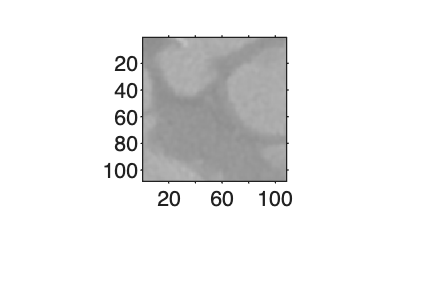

options = trainingOptions("adam", ...

    MaxEpochs=50, ...
    InitialLearnRate=5e-4, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=5, ...
    LearnRateDropFactor=0.95, ...
    ValidationData=dsVal, ...
    ValidationFrequency=400, ...
    Plots="training-progress", ...
    Verbose=false, ...
    MiniBatchSize=miniBatchSize);

### Define Loss Function

Define a custom loss function, `generalizedDiceLoss`, that takes predictions `Y` and targets `T` and returns the Generalized Dice loss. The Generalized Dice similarity coefficient measures the overlap between two segmented images. The coefficient is based on Sørensen-Dice similarity, and controls the contribution that each class makes to the similarity by weighting classes by the inverse size of the expected region. For more details, see [`generalizedDice`](docid:vision_ref#mw_479dae53-4172-47df-9a5e-a53a75a4d2e5).

function loss = generalizedDiceLoss(Y,T)
    % Ignore any NaNs introduced to the training data during augmentation
    T(isnan(T)) = 0;

    z = generalizedDice(Y,T);
    % Calculate the mean of the Dice loss across the batch
    loss = 1 - mean(z,"all");
end

### Train Network

By default, the example uses the downloaded pretrained 3-D U-Net network. The pretrained network enables you to perform semantic segmentation and evaluate the segmentation results without waiting for training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. Train the network using the [`trainnet`](docid:nnet_ref#mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. By default, the `trainnet` function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

doTraining = true;
if doTraining
    [trainedNet,info] = trainnet(dsTrain,net,@generalizedDiceLoss,options);
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save("trained3DUNet-"+modelDateTime+".mat","trainedNet");
end

Y size:
    20    20    20     3     4

T size:
    20    20    20     3     4

Y class:
dlarray
T class:
dlarray
Y underlying type: single
T underlying type: single
Training stopped: Error occurred


Error using trainnet (line 58)
Error evaluating loss function.

Caused by:
    Undefined function 'isformatted' for input arguments of type 'dlarray'.
    
    Error in Segment3DCardiacUsingDeepLearning>generalizedDiceLoss (line 96)
        isYFormatted = isformatted(Y);
               

## Evaluate 3-D U-Net

Specify the location of the data to use for testing the network. By default, `useFullTestSet` is `false` and the example uses the five sample volumes downloaded in the Load Sample BraTS Data section. If you change the `useFullTestSet` value to `true`, then the example uses 55 of the scans allocated to testing from the full data set.

useFullTestSet = false;
if useFullTestSet
    volLocTest = fullfile(preprocessDataLoc,"imagesTest");
    lblLocTest = fullfile(preprocessDataLoc,"labelsTest");
else
    volLocTest = fullfile(testDir,"imagesTest");
    lblLocTest = fullfile(testDir,"labelsTest");
end

Similar to the training and validation data sets, manage the image data and labels for the testing data set by creating an `imageDatastore` object and `pixelLabelDatastore` object, respectively.

voldsTest = imageDatastore(volLocTest,FileExtensions=".mat", ...
    ReadFcn=@matRead);

pxdsTest = pixelLabelDatastore(lblLocTest,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

For each test volume, read the volume as a `blockedImage` object and process each block using the [`apply`](docid:images_ref#mw_d2a929bc-2fd0-45b6-b4ed-0e2671850b23) function. The `apply` function performs the operations specified by the `calculateBlockMetrics` helper function, which is defined at the end of this example. The `calculateBlockMetrics` function performs semantic segmentation of each block, and calculates the confusion matrix between the predicted and ground truth labels.

imageIdx = 1;
datasetConfMat = table;
while hasdata(voldsTest)

    % Read volume and label data
    vol = read(voldsTest);
    volLabels = read(pxdsTest);

    % Create blockedImage for volume and label data
    testVolume = blockedImage(vol);
    testLabels = blockedImage(volLabels{1});

    % Calculate block metrics
    blockConfMatOneImage = apply(testVolume, ...
        @(block,labeledBlock) ...
            calculateBlockMetrics(block,labeledBlock,trainedNet,classNames), ...
        ExtraImages=testLabels, ...
        PadPartialBlocks=true, ...
        BlockSize=blockSize, ...
        BorderSize=borderSize);

    % Read all the block results of an image and update the image number
    blockConfMatOneImageDS = blockedImageDatastore(blockConfMatOneImage);
    blockConfMat = readall(blockConfMatOneImageDS);
    blockConfMat = struct2table([blockConfMat{:}]);
    blockConfMat.ImageNumber = imageIdx.*ones(height(blockConfMat),1);
    datasetConfMat = [datasetConfMat; blockConfMat];

    imageIdx = imageIdx + 1;
end

Evaluate the data set metrics and block metrics for the segmentation using the [`evaluateSemanticSegmentation`](docid:vision_ref#mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) function.

[metrics,blockMetrics] = evaluateSemanticSegmentation( ...
    datasetConfMat,classNames,Metrics="all");

Display the Jaccard score calculated for each image.

metrics.ImageMetrics.MeanIoU

## Supporting Function

The `calculateBlockMetrics` helper function performs semantic segmentation of a block, and calculates the confusion matrix between the predicted and ground truth labels. The function returns a structure with fields containing the confusion matrix and metadata about the block. You can use the structure with the `evaluateSemanticSegmentation` function to calculate metrics and aggregate block-based results.

function blockMetrics = calculateBlockMetrics(bstruct,gtBlockLabels,net,classNames)

% Segment block
predBlockLabels = semanticseg(bstruct.Data,net,Classes=classNames);

% Trim away border region from gtBlockLabels 
blockStart = bstruct.BorderSize + 1;
blockEnd = blockStart + bstruct.BlockSize - 1;
gtBlockLabels = gtBlockLabels( ...
    blockStart(1):blockEnd(1), ...
    blockStart(2):blockEnd(2), ...
    blockStart(3):blockEnd(3));

% Evaluate segmentation results against ground truth
confusionMat = segmentationConfusionMatrix(predBlockLabels,gtBlockLabels);

% blockMetrics is a struct with confusion matrices, image number,
% and block information 
blockMetrics.ConfusionMatrix = confusionMat;
blockMetrics.ImageNumber = bstruct.ImageNumber;
blockInfo.Start = bstruct.Start;
blockInfo.End = bstruct.End;
blockMetrics.BlockInfo = blockInfo;

end

## References

[1] Çiçek, Özgün, Ahmed Abdulkadir, Soeren S. Lienkamp, Thomas Brox, and Olaf Ronneberger. “3D U-Net: Learning Dense Volumetric Segmentation from Sparse Annotation.” In *Medical Image Computing and Computer-Assisted Intervention – MICCAI 2016*, edited by Sebastien Ourselin, Leo Joskowicz, Mert R. Sabuncu, Gozde Unal, and William Wells, 9901:424–32. Cham: Springer International Publishing, 2016. [https://doi.org/10.1007/978-3-319-46723-8_49](https://doi.org/10.1007/978-3-319-46723-8_49).

[2] Isensee, Fabian, Philipp Kickingereder, Wolfgang Wick, Martin Bendszus, and Klaus H. Maier-Hein. “Brain Tumor Segmentation and Radiomics Survival Prediction: Contribution to the BRATS 2017 Challenge.” In *Brainlesion: Glioma, Multiple Sclerosis, Stroke and Traumatic Brain Injuries*, edited by Alessandro Crimi, Spyridon Bakas, Hugo Kuijf, Bjoern Menze, and Mauricio Reyes, 10670:287–97. Cham: Springer International Publishing, 2018. [https://doi.org/10.1007/978-3-319-75238-9_25](https://doi.org/10.1007/978-3-319-75238-9_25).

[3] "Brain Tumours". *Medical Segmentation Decathlon.* http://medicaldecathlon.com/ 

The BraTS dataset is provided by Medical Segmentation Decathlon under the [CC-BY-SA 4.0 license.](https://creativecommons.org/licenses/by-sa/4.0/) All warranties and representations are disclaimed; see the license for details. MathWorks® has modified the data set linked in the Load Sample BraTS Data section of this example. The modified sample data set has been cropped to a region containing primarily the brain and tumor, and each channel has been normalized independently by subtracting the mean and dividing by the standard deviation of the cropped brain region.

[4] Sudre, Carole H., Wenqi Li, Tom Vercauteren, Sebastien Ourselin, and M. Jorge Cardoso. “Generalised Dice Overlap as a Deep Learning Loss Function for Highly Unbalanced Segmentations.” In *Deep Learning in Medical Image Analysis and Multimodal Learning for Clinical Decision Support*, edited by M. Jorge Cardoso, Tal Arbel, Gustavo Carneiro, Tanveer Syeda-Mahmood, João Manuel R.S. Tavares, Mehdi Moradi, Andrew Bradley, et al., 10553:240–48. Cham: Springer International Publishing, 2017. [https://doi.org/10.1007/978-3-319-67558-9_28](https://doi.org/10.1007/978-3-319-67558-9_28).

[5] Ronneberger, Olaf, Philipp Fischer, and Thomas Brox. “U-Net: Convolutional Networks for Biomedical Image Segmentation.” In *Medical Image Computing and Computer-Assisted Intervention – MICCAI 2015*, edited by Nassir Navab, Joachim Hornegger, William M. Wells, and Alejandro F. Frangi, 9351:234–41. Cham: Springer International Publishing, 2015. [https://doi.org/10.1007/978-3-319-24574-4_28](https://doi.org/10.1007/978-3-319-24574-4_28).

*Copyright 2019-2024 The MathWorks, Inc.*